# C1 - Fourier Transform

## Part a)

First, we define constants and the n-range

Nt = 128;
fs = 1000;
f0 = 5/128*fs;
a = 0.5;
phi = pi/2;
n = 0:Nt-1;

Then we define our anonymous function y(n) and plot it

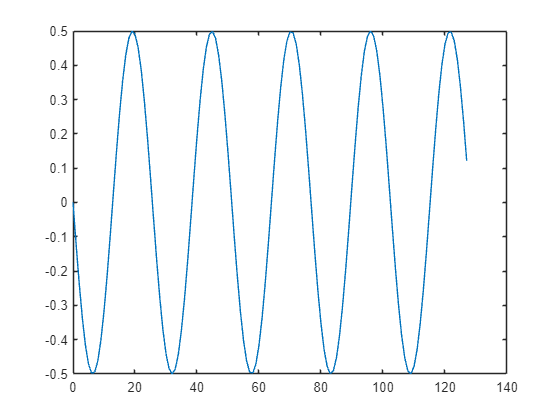

y = @(n) (n<0).*(0) + (n>=0 & n<=Nt-1).*(a*cos(2*pi*f0*n/fs+phi)) + (n>Nt-1).*(0);

plot(n, y(n))

## Part b)

Now we define constants for the transffourier function

Nf = 128;

And we compute the discrete fourier transform

[f, tfx] = transffourier(y(n), Nf, fs);

and plot it in the frequency domain

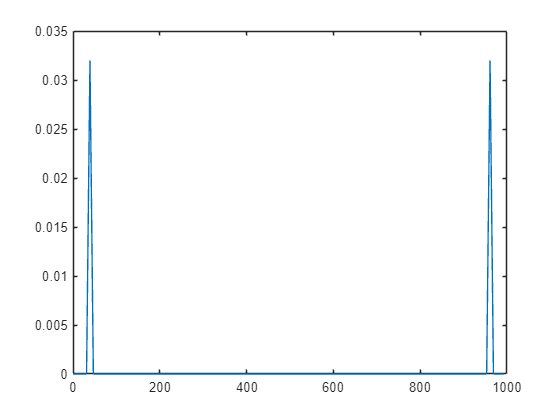

plot(f, abs(tfx))

and to find the peaks we calculate:

[pks, locs] = findpeaks(abs(tfx), f, 'MinPeakHeight',0.1*max(abs(tfx)))

pks =     0.0320
    0.0320


locs =    39.0625  960.9375


to explain the positions of these peaks we compare the true and sampling frequencies based on the shannon formula

f_observed = min(k) |+/- f_actual + k*f_s|

fs

fs = 1000

f0

f0 = 39.0625

The minimum is reached for k=0 and we see

f_observed1 = +f0 + 0*fs

f_observed1 = 39.0625

which generates the peak at

locs(1)

ans = 39.0625

where the second peak at

locs(2)

ans = 960.9375

takes its value from k=1

f_observed2 = -f0 + 1*fs

f_observed2 = 960.9375

## Part c)

Instruction says to plot the magnitude spectrum with cross marker for Nf=128

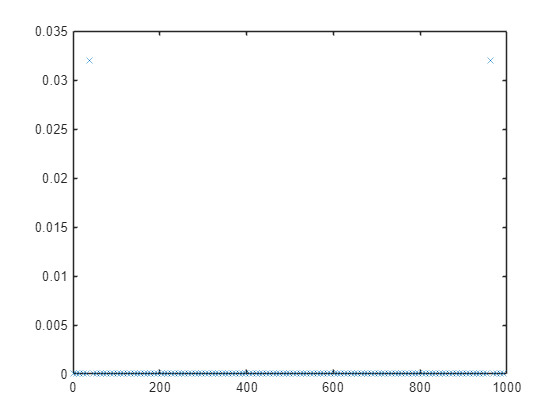

plot(f, abs(tfx), 'x')

as well as the full line magnitude spectrum for Nf=4096

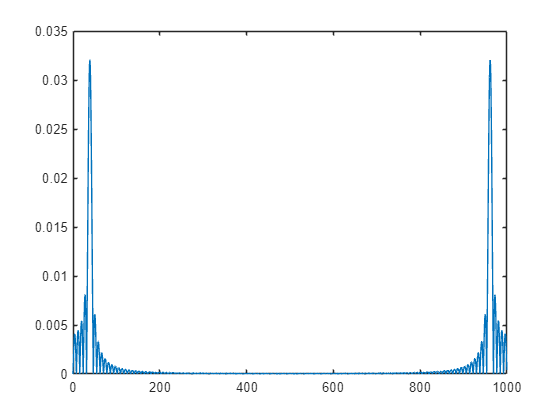

Nf2=4096;
[f2, tfx2] = transffourier(y(n), Nf2, fs);
plot(f2, abs(tfx2))

## Part d)

The instructions say to redo all calculations but with f0=5.7/128*fs

f0 = 5.7/128 * fs

f0 = 44.5312

We need not initialise all constants and functions again, all that is required to start is

Nf = 128;

And we can proceed to part a)

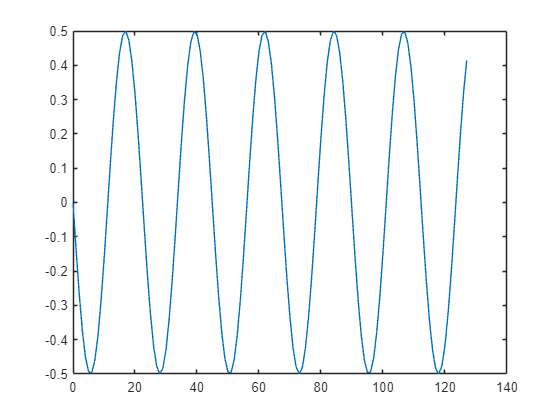

yd=@(n) (n<0).*(0) + (n>=0 & n<=Nt-1).*(a*cos(2*pi*f0*n/fs+phi)) + (n>Nt-1).*(0);
plot(n, yd(n))

then to part b)

the lines below in order are Compute, Plot, Peaks, f_observed from Shannon x2 

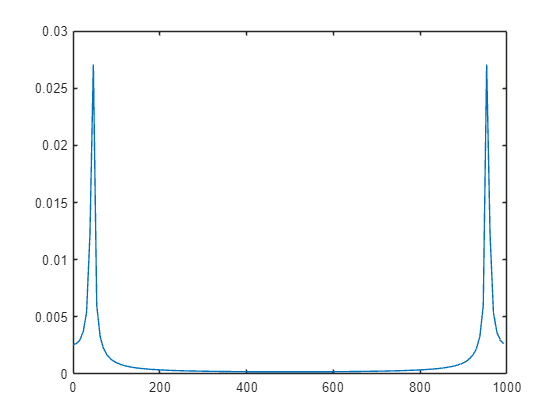

[fd1, tfxd1] = transffourier(yd(n), Nf, fs);
plot(fd1, abs(tfxd1))

[pksd, locsd] = findpeaks(abs(tfxd1), fd1, 'MinPeakHeight',0.1*max(abs(tfxd1)))

pksd =     0.0271
    0.0271


locsd =    46.8750  953.1250


f_observed1 = +f0 + 0*fs

f_observed1 = 44.5312

f_observed2 = -f0 + 1*fs

f_observed2 = 955.4688

We can explain the divergence between locsd and f_observed by recalling Nf is a very small 128 as opposed to part c)

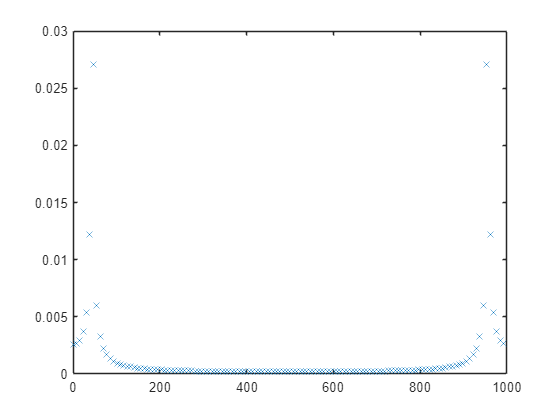

plot(fd1, abs(tfxd1), 'x')

And now for the full spectrum at 4096 frequencies

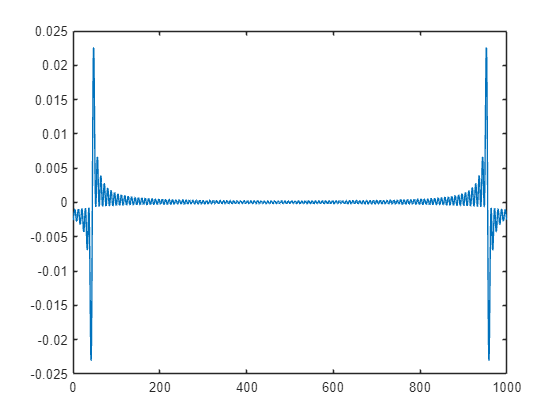

Nfd2=4096;
[fd2, tfxd2] = transffourier(yd(n), Nf2, fs);
plot(fd2, tfxd2)